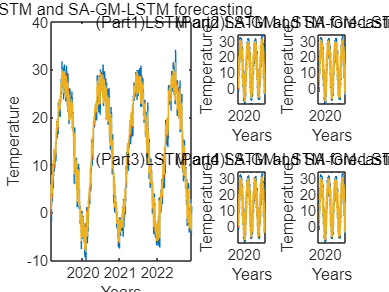

load("matlab5.mat")
load("YPredForSAGM.mat")
load("YPredForLSTM.mat")
for i = 1 : 1380
    y(i) = PekingTemp(i + 4745);
end
y1 = YPredForSAGM;
y2 = YPredForLSTM;
x = 2019:(1/365):(2022+(364-80)/365);
for i = 1 : 1380
    x(i) = x(i) + 0.15;
end

figure
subplot(2,4,[1,2,5,6])
plot(x,y,x,y1,x,y2)
var1 = var(y1);
var2 = var(y2);
xlabel("Years")
ylabel("Temperature")
title("LSTM and SA-GM-LSTM forecasting")

subplot(2,4,3)
plot(x,y,x,y1,x,y2,'LineWidth',1.2)
var1 = var(y1);
var2 = var(y2);
xlabel("Years")
ylabel("Temperature")
title("(Part1)LSTM and SA-GM-LSTM forecasting")

subplot(2,4,4)
plot(x,y,x,y1,x,y2,'LineWidth',1.2)
var1 = var(y1);
var2 = var(y2);
xlabel("Years")
ylabel("Temperature")
title("(Part2)LSTM and SA-GM-LSTM forecasting")

subplot(2,4,7)
plot(x,y,x,y1,x,y2,'LineWidth',1.2)
var1 = var(y1);
var2 = var(y2);
xlabel("Years")
ylabel("Temperature")
title("(Part3)LSTM and SA-GM-LSTM forecasting")

subplot(2,4,8)
plot(x,y,x,y1,x,y2,'LineWidth',1.2)
var1 = var(y1);
var2 = var(y2);
xlabel("Years")
ylabel("Temperature")
title("(Part4)LSTM and SA-GM-LSTM forecasting")